clf
%序列递推
%差分方程 ： y(n)-2*y(n-1)+y(n-2)=x(n-1)  
y_2=2; y_1=1; x_1=0; x0=0;     %初始条件
x=1:10;                        %激励序列x(n)
y_0=0;
y=[-1,-1];
for n=3:10
     y=[y,2*y(end)-y(end-1)+x(n-1)];    %序列递推
end
y%显示数列
stem(y);
xlabel('n');
ylabel('y(n)');
title('递推后的序列y');

clf
%幅频特性与相频特性计算，画出零极点
figure 
b=[0,1];
a=[1,-2,1];              %选用系统函数为：H（z）=z/(1-z)^2
[r,p,k]=residue(b,a)     %求z反变换
zplane(b,a);title('零极点图');       %零极点图，z=1是二阶极点
figure
n=0:10;
h=impz(b,a,11)
stem(n,h,'filled'); title('冲激响应h(n)');    %冲激响应图,h(n)=n*u(n)
figure
w=pi*freqspace(100);
freqz(b,a,w); title('幅频特性与相频特性');     %系统频率响应的幅频特性和相频特性图

clf
%序列的线性卷积计算
x=[3,11,7,0,-1,4,2];   
h=[2,3,0,-5,2,1];        
y=conv(x,h);                %求线性卷积
subplot(3,1,1)   
stem(0:length(x)-1,x,'filled');         
xlabel('n'); ylabel('幅度'); title('x');      
subplot(3,1,2)
stem([0:length(h)-1],h,'filled');        
xlabel('n'); ylabel('幅度'); title('h')
subplot(3,1,3)
stem([0:length(y)-1],y,'filled');           
xlabel('n'); ylabel('幅度'); title('线性卷积')

clf%验证离散傅里叶变换的对称性
N=8;a=0.7;
n=[0:N-1];
xn=a.^n;
k=n;
WN=exp(-j*2*pi/N);
nk=n'*k;
WNnk=WN.^nk;
Xk=xn*WNnk;                           %求出DFT变换
subplot(3,1,1)
stem(n,xn,'.k'); axis([0,8,0,1.5])    %原序列
title('X(n) a=0.7');
subplot(3,1,2)
stem(n,abs(Xk),'.k'); axis([0,8,0,5])                 %幅度特性
title('X(k)幅度');
subplot(3,1,3)
stem(n,angle(Xk),'.k'); axis([0,8,-1.5,1.5])          %相位特性
title('X(k)相位');


clf%三角波序列与反三角波序列的频谱对比
N=8;n=0:N-1;
xc=[1:4,4:-1:1];     %三角波序列
xd=[4:-1:1,1:4];     %反三角序列
Xck=fft(xc,N);      
Xdk=fft(xd,N);      
subplot(2,2,1)
stem(n,xc,'.k');  title('三角波序列时域波形');               
subplot(2,2,3)
stem(n,abs(Xck),'.k');  title('三角波序列幅频特性|Xc(k)|');  %幅频特性
axis([0,8,0,10])
subplot(2,2,2)
stem(n,xd,'.k');  title('反三角波序列时域波形');         
subplot(2,2,4)
stem(n,abs(Xdk),'.k');  title('三角波序列幅频特性|Xd(k)|');  %幅频特性
axis([0,8,0,10])
figure
subplot(2,1,1)
[Hc,w]=freqz(xc,[1,zeros(1,7)]);plot(w,abs(Hc));grid on;       
title('三角波的单位圆上Z变换频谱|Xc(jw)|');
subplot(2,1,2)
[Hd,w]=freqz(xd,[1,zeros(1,7)]);plot(w,abs(Hd));grid on;        
title('反三角波的单位圆上Z变换频谱|Xd(jw)|');      


clf%不同F、N、T条件下的FFT变换对比
F=50;N=32;T=[0.000625,0.005,0.0046875,0.004];
n=0:N-1; xn=zeros(4,N);Xk=zeros(4,N);
label={'F=50, N=32,T=0.000625';'F=50, N=32,T=0.005';'F=50, N=32,T=0.0046875';'F=50, N=32,T=0.004';'F=50, N=64，T=0.000625'};
for m=1:4
   subplot(5,1,m)
   xn(m,:)=cos(2*pi*F*T(m).*n);
   Xk(m,:)=fft(xn(m,:),N);        
   stem(n,abs(Xk(m,:)),'.k');     %幅频特性
   title(label(m));
end
subplot(5,1,5)
F=50;N=64;T=0.000625;
n=0:N-1;xn5=cos(2*pi*F*T.*n);Xk5=fft(xn5,N);
stem(n,abs(Xk5),'.k');title(label(5));


clf%DFT与FFT运行时间
N=1024;M=80;x=[1:M,zeros(1,N-M)];
t=cputime;                    
y1=fft(x,N);
Time_fft=cputime-t              %得到FFT时间
t1=cputime;
n=0:N-1;
k=n;WN=exp(-1i*2*pi/8);nk=n'*k;
WNnk=WN.^nk;
y2=x*WNnk;             
Time_dft=cputime-t1             %得到DFT时间


clf%利用FFT的循环卷积计算线性卷积
n=0:14;
x=ones(1,15);
h=(0.8).^n;
L=length(x)+length(h)-1;
X=fft(x,L);
H=fft(h,L);
y=ifft(X.*H);           %得到卷积后的序列
figure
subplot(3,3,1);stem(n,x,'filled');title('x(n)');
subplot(3,3,4);stem(n,h,'filled');title('h(n)');
n=0:L-1;
subplot(3,3,7);stem(n,real(y),'filled');title('卷积结果y(n)');
n=0:19;
x=[ones(1,10),zeros(1,10)];
h=0.5*sin(0.5.*n);
L=length(x)+length(h)-1;
X=fft(x,L);
H=fft(h,L);
y=ifft(X.*H);           %得到卷积后的序列
subplot(3,3,2);stem(n,x,'filled');title('x(n)');
subplot(3,3,5);stem(n,h,'filled');title('h(n)');
n=0:L-1;
subplot(3,3,8);stem(n,real(y),'filled');title('卷积结果y(n)');
n=0:9;
x=1-0.1.*n;
h=0.1.*n;
L=length(x)+length(h)-1;
X=fft(x,L);
H=fft(h,L);
y=ifft(X.*H);            %得到卷积后的序列
subplot(3,3,3);stem(n,x,'filled');title('x(n)');
subplot(3,3,6);stem(n,h,'filled');title('h(n)');
n=0:L-1;
subplot(3,3,9);stem(n,real(y),'filled');title('卷积结果y(n)');

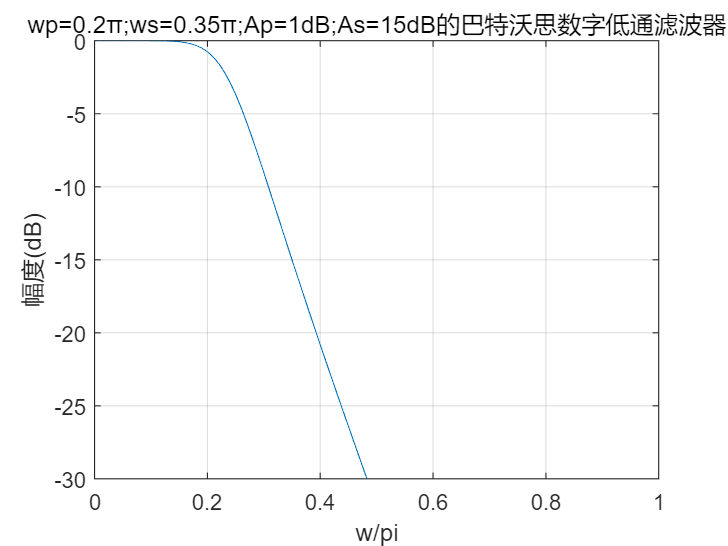


clf%设计数字滤波器
wp=0.2;ws=0.35;Ap=1;As=15;     
[N,fc]=buttord(wp,ws,Ap,As);    %求出符合参数的滤波器阶数和截止频率
[B,A]=butter(N,fc);             %得到滤波器H(z)的系数
[h,w]=freqz(B,A,1024);          %计算模拟滤波器响应
plot(w/pi,20*log10(abs(h)/abs(h(1))));
title('wp=0.2π;ws=0.35π;Ap=1dB;As=15dB的巴特沃思数字低通滤波器');
grid on;xlabel('w/pi');ylabel('幅度(dB)');
axis([0,1,-30,0])

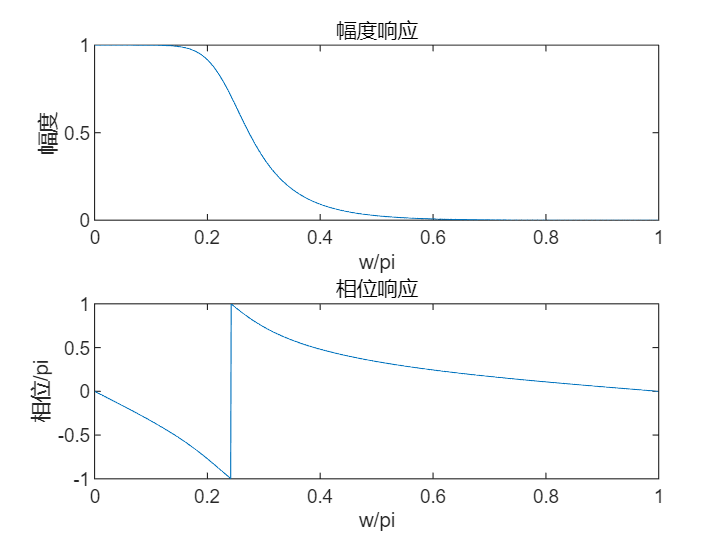


clf%数字滤波器的幅度特性与相位特性
wp=0.2;ws=0.35;Ap=1;As=15;
[N,fc]=buttord(wp,ws,Ap,As);  %求出符合参数的巴特沃思滤波器阶数和截止频率
[b,a]=butter(N,fc);              %得到滤波器H(z)的系数
[h,w]=freqz(b,a,1024);           %计算数字滤波器响应
subplot(2,1,1);plot(w/pi,abs(h));title('幅度响应');     %数字滤波器幅度特性
xlabel('w/pi');ylabel('幅度');
subplot(2,1,2);plot(w/pi,angle(h)/pi);title('相位响应'); %数字滤波器相频特性
xlabel('w/pi');ylabel('相位/pi');

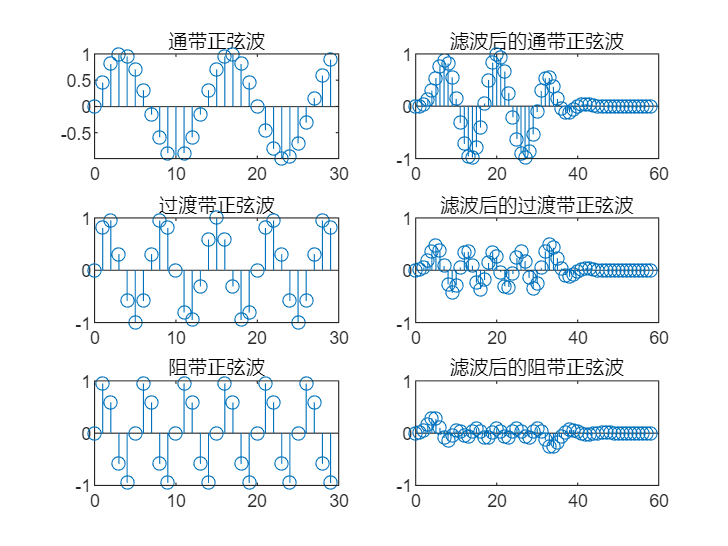


clf%实现各个频率的正弦波的数字滤波
wp=0.2;ws=0.35;Ap=1;As=15;
[N,fc]=buttord(wp,ws,Ap,As);    %求出符合参数的巴特沃思滤波器阶数和截止频率
[b,a]=butter(N,fc);             %得到滤波器H(z)的系数
[H,w]=freqz(b,a,1024);          %计算数字滤波器响应
[h,n]=impz(b,a,30);
w1=0.15*pi;w2=0.3*pi;w3=0.4*pi;
x1=sin(w1.*n);x2=sin(w2.*n);x3=sin(w3.*n); %正弦波频率:通带、过渡带、阻带
figure
subplot(3,2,1);   stem(n,x1); title('通带正弦波'); %原通带正弦波
subplot(3,2,2);   y1=conv(x1,h); stem(0:length(y1)-1,y1);axis([0,60,-1,1]); title('滤波后的通带正弦波'); 
subplot(3,2,3);   stem(n,x2); title('过渡带正弦波'); %原过渡带正弦波   
subplot(3,2,4);   y2=conv(x2,h); stem(0:length(y2)-1,y2);axis([0,60,-1,1]); title('滤波后的过渡带正弦波'); 
subplot(3,2,5);   stem(n,x3); title('阻带正弦波');  %原阻带正弦波
subplot(3,2,6);   y3=conv(x3,h); stem(0:length(y3)-1,y3);axis([0,60,-1,1]); title('滤波后的阻带正弦波'); 

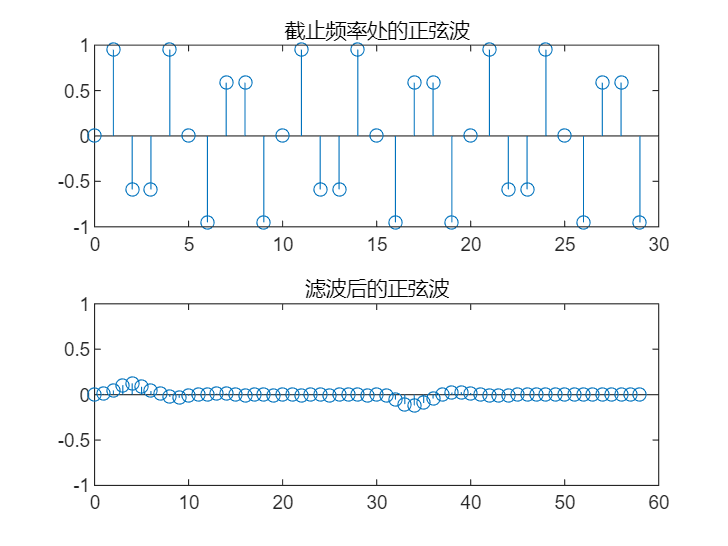

figure      
w4=0.6*pi;x4=sin(w4.*n);  %验证滤波器的模拟截止频率，滤波后的幅度几乎全0
subplot(2,1,1);   stem(n,x4); title('截止频率处的正弦波'); 
subplot(2,1,2);   y4=conv(x4,h); stem(0:length(y4)-1,y4);axis([0,60,-1,1]); title('滤波后的正弦波'); 

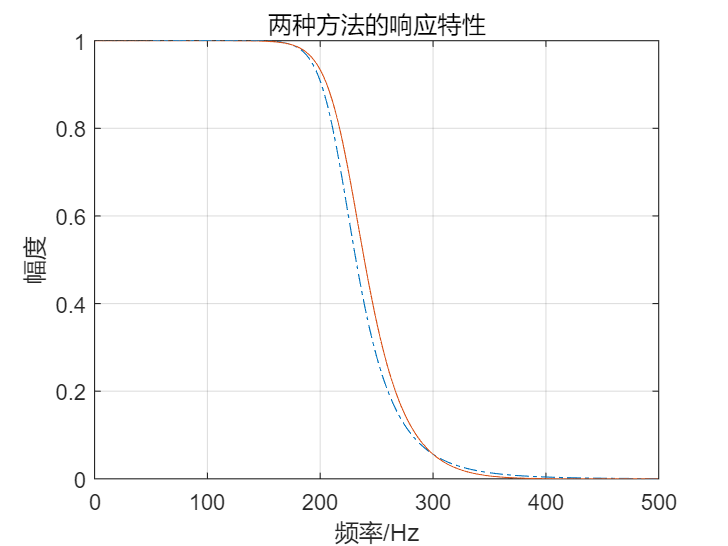


clf%冲激响应不变法与双极性变换法的对比
fp=200;fs=300;Rp=1;As=25;T=0.001;
%使用脉冲响应不变法（存在频率混叠）
wp=2*pi*fp*T;ws=2*pi*fs*T;  %wp、ws为数字频率
Wp=wp/T;Ws=ws/T;            %Wp、Ws为模拟频率
[N1,fc]=buttord(Wp,Ws,Rp,As,'s');
[b,a]=butter(N1,fc,'s');
[b1,a1]=impinvar(b,a,1/T);   %冲击响应不变法变换到数字滤波器
[h1,w]=freqz(b1,a1); 
%使用双极性变换法（不存在频率混叠）
Wp=2/T*tan(wp/2);Ws=2/T*tan(ws/2);  %频率预畸变
[N1,fc]=buttord(Wp,Ws,Rp,As,'s');   
[b,a]=butter(N1,fc,'s');
[b2,a2]=bilinear(b,a,1/T);   %双极性变换法变换到数字滤波器
[h2,w]=freqz(b2,a2);
f=w/2/pi/T; figure;
plot(f,abs(h1),'-.',f,abs(h2),'-');

axis([0,500,0,1]);grid on;
xlabel('频率/Hz');ylabel('幅度');title('两种方法的响应特性');